# 定义全局变量

R1 = 5;  % 内芯半径
R2 = 12; % 外导体内径
R3 = 15; % 外导体外径
u0 = 4*pi*1e-7;  % 真空磁导率
I = 2;   % 电流大小
B = 0;   % 用来计算磁感应强度
r = 0;   % 用来计算磁感应强度
num = 5; % 用来绘制磁感应强度圈数

## 绘制初始目标

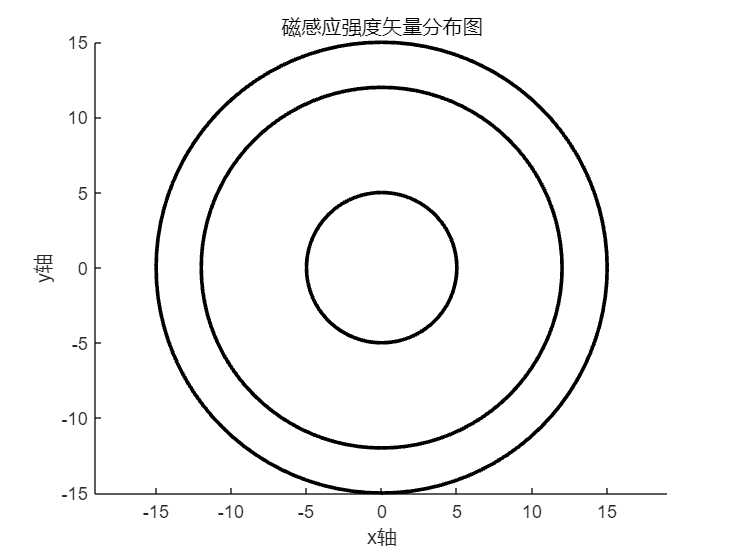

% 绘制外芯线
rectangle('Position', [0-R2,0-R2,2*R2,2*R2], 'Curvature', [1 1],'EdgeColor', 'black', 'LineWidth', 2);
rectangle('Position', [0-R3,0-R3,2*R3,2*R3], 'Curvature', [1 1],'EdgeColor', 'black', 'LineWidth', 2);
% 绘制内芯线
rectangle('Position', [0-R1,0-R1,2*R1,2*R1], 'Curvature', [1 1],'EdgeColor', 'black', 'LineWidth', 2);
xlabel('x轴')
ylabel('y轴')
title('磁感应强度矢量分布图')
axis equal
hold on


% 计算磁感应强度位置(r,f,z)的直角坐标位置，以及对应的单位矢量
[x, y, a_x, a_y] = Get_Cycle_xy(r, 20);


## 绘制图形

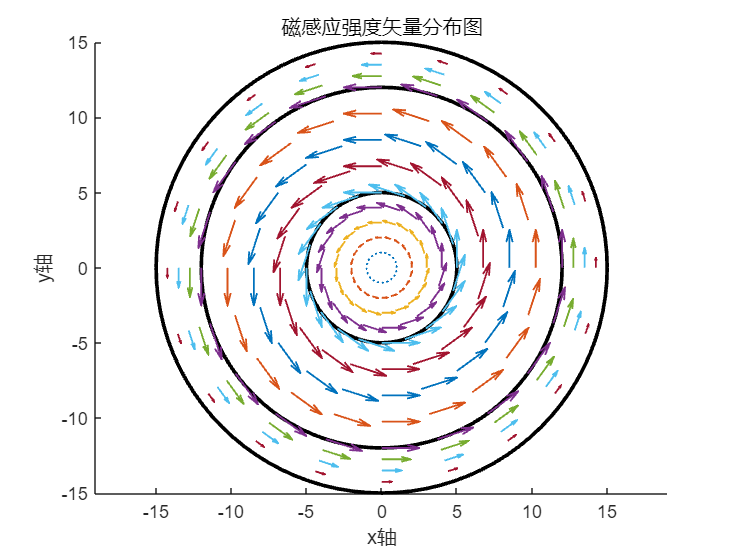

% r <= R1
for r = linspace(1, R1, num)
    [x, y, a_x, a_y] = Get_Cycle_xy(r, 20);
    r_B = Get_B(r, R1, R2, R3, u0, I) * 1e7;
    if r_B ~= 0
        quiver(x, y, a_x, a_y, r_B, LineWidth=1)
    end
end
hold on
% R1 < r <= R2
for r = linspace(R1, R2, num)
    [x, y, a_x, a_y] = Get_Cycle_xy(r, 20);
    r_B = Get_B(r, R1, R2, R3, u0, I) * 1e7;
    if r_B ~= 0
        quiver(x, y, a_x, a_y, r_B, LineWidth=1)
    end
end
% R2 < r <= R3
for r = linspace(R2, R3, num)
    [x, y, a_x, a_y] = Get_Cycle_xy(r, 20);
    r_B = Get_B(r, R1, R2, R3, u0, I) * 1e7;
    if r_B ~= 0
        quiver(x, y, a_x, a_y, r_B, LineWidth=1)
    end
end
% r > R3
for r = linspace(R3, 2*R3, num)
    [x, y, a_x, a_y] = Get_Cycle_xy(r, 20);
    r_B = Get_B(r, R1, R2, R3, u0, I) * 1e7;
    if r_B ~= 0
        quiver(x, y, a_x, a_y, r_B, LineWidth=1)
    end
end
hold off

## 绘制磁感应强度B与距离r之间的关系

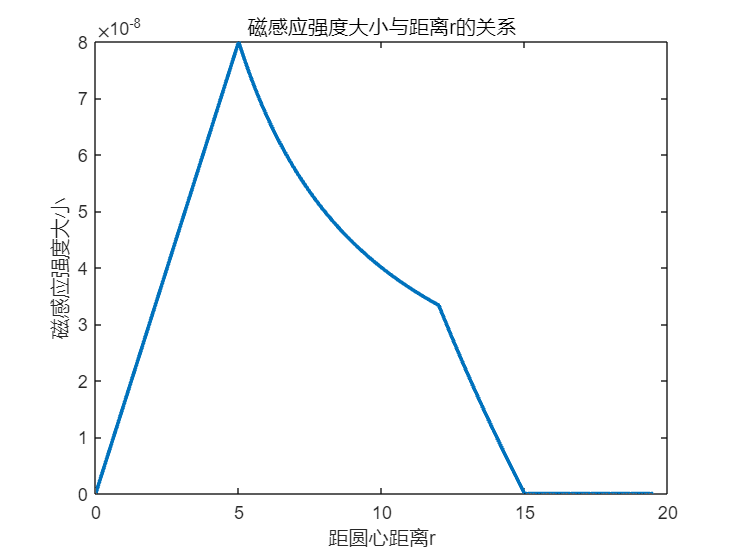

plot_r = 0:0.1:1.3*R3;
plot_r_B = zeros(size(plot_r));
for i = 1:length(plot_r)
    plot_r_B(i) = Get_B(plot_r(i), R1, R2, R3, u0, I);
end
plot(plot_r, plot_r_B, LineWidth=2)
title('磁感应强度大小与距离r的关系')
ylabel('磁感应强度大小')
xlabel('距圆心距离r')

## 绘制类似海拔图

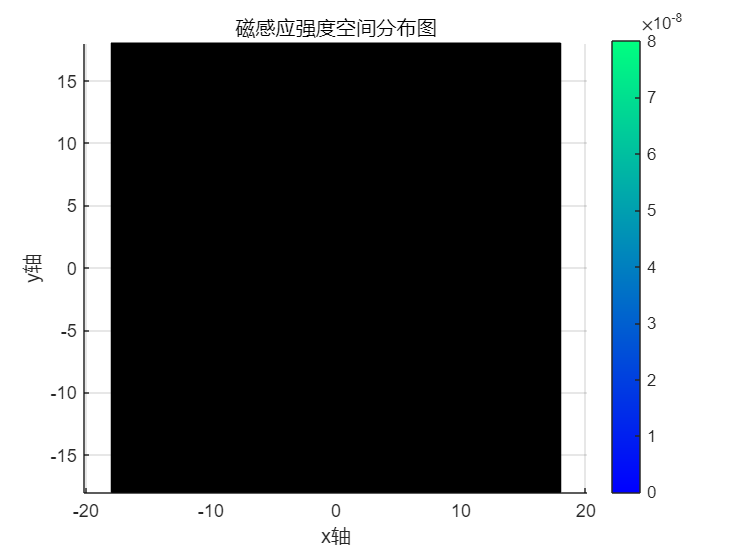

%% 插值之后再绘制就会密集了
[x0, y0] = meshgrid(-1.2*R3:0.01:1.2*R3, -1.2*R3:0.01:1.2*R3);
z0 = zeros(size(x0));
for i = 1:length(x0)^2
    z0(i) = Get_B(sqrt(x0(i)^2 + y0(i)^2), R1, R2, R3, u0, I);
end
mesh(x0, y0, z0);
colormap(parula(256)); %设置colormap的格式
colorbar; %加上色条
view(0, 90);
xlabel('x轴')
ylabel('y轴')
title('磁感应强度大小空间分布图')
% axis([0, 1.2*R3, 0, 1.2*R3])
axis equal
hold on